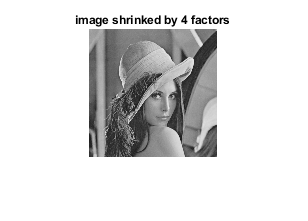

I = im2uint8(rgb2gray(imread('lena_std.tif')));

% Q1a
shinked_res = q1(I,-4);
imshow(shinked_res), title("image shrinked by 4 factors");

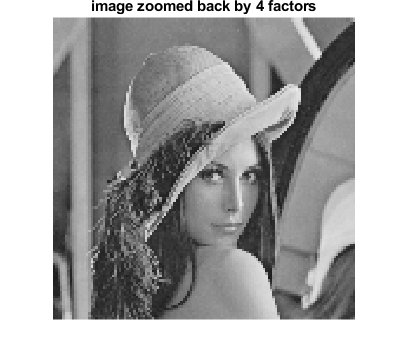


% Q1b
zoomed_res = q1(shinked_res,4);
imshow(zoomed_res), title("image zoomed back by 4 factors");

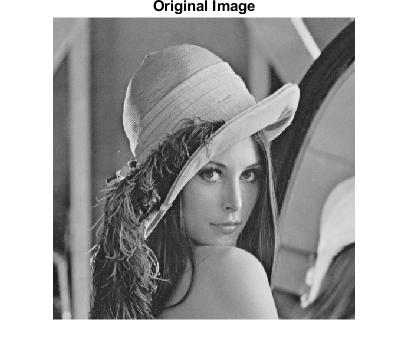


% Q2a
I = im2uint8(rgb2gray(imread('lena_std.tif')));
imshow(I), title("Original Image");

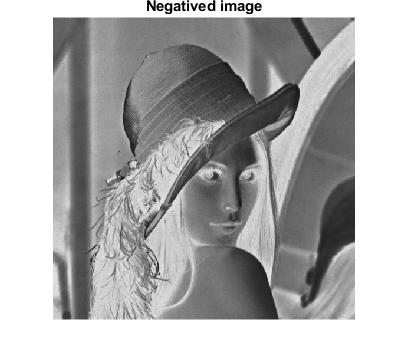


% Q2b
img_neg = 255 - I;
imshow(img_neg), title("Negatived image");

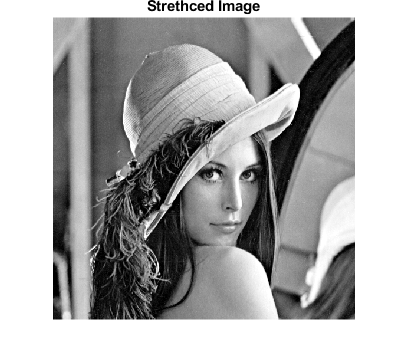


% Q2c
stretched_img = imadjust(I,stretchlim(I,[0.01,0.99]),[]);
imshow(stretched_img), title("Strethced Image");

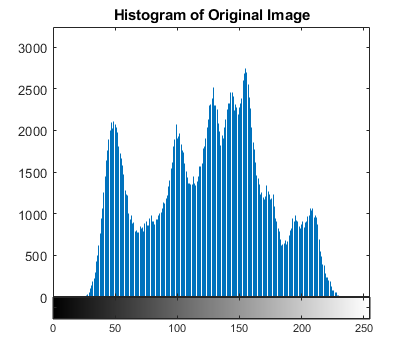

imhist(I), title("Histogram of Original Image");

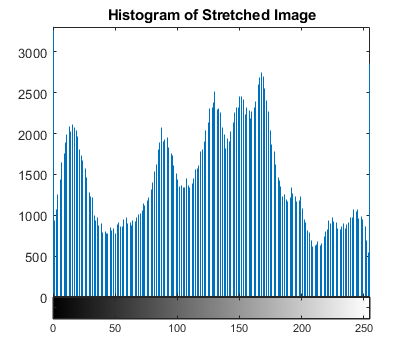

imhist(stretched_img), title("Histogram of Stretched Image");

function res = q1(img, f)
    f = int32(f);
    [r,c] = size(img);

    % image zooming
    if f>0
        % row pixel replication
        for i = 1:r
            for j = 1:c
                for k = 1:f
                    img2(i,(j-1)*f+k) = img(i,j);
                end
            end
        end
        % col pixel replication
        [r,c] = size(img2);
        for i = 1:r
            for j = 1:c
                for k = 1:f
                    res((i-1)*f+k,j) = img2(i,j);
                end
            end
        end

    % image shrinking
    elseif -c<f&&-r<f&&f<0
        % row pixel deletion
        for i=1:r/(-f)
            for j = 1:c
                img2(i,j) = img((i-1)*(-f)+1,j);
            end
        end
        %col pixel deletion
        [r,c] = size(img2);
        for i = 1:r
            for j = 1:c/(-f)
                res(i,j) = img2(i,(j-1)*(-f)+1);
            end
        end

    % image does not change if f equals 0 or less than image size
    else
        res = img;
    end
end